addpath('functions/');

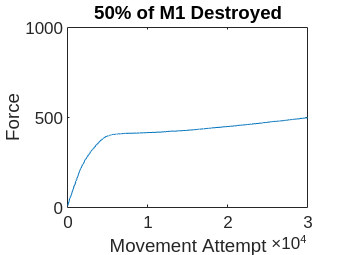

% Creating n Corticalspinal cells
n = 1000; 

% Initalize the base CS cells
% 80% of the n Cortical cells are M1
m1_count = n * 0.8;
m1_destroyed = m1_count * 0.5;
m1_alive = m1_count * 0.5;
m1 = [zeros(1, m1_destroyed), -1 + (1+1)*rand(1, m1_alive)];
% 20& of the n Cortical cells are SMA
sma_count = n * 0.2;
sma = -1 + (1+1)*rand(1, sma_count);

x_0 = [m1, sma];

% 80% of the n Cortical cells are M1
agonist_count = n * 1;
agonist = randperm(agonist_count);
m1_count = agonist_count * 0.8;

% Parameters for zero-mean normal distribution
std_dev = 0.02;
mean = 0;

% CS extensor and flexor connection weights
c_fi = ones(1, n);
for i = 1:length(c_fi)    
    if i > m1_count
        % SMA
        c_fi(i) = 0.1*c_fi(i);
    end
end

% Translating MN pool to force
delta = 1;

sma = [];
m1 = [];
final_forces = [];
f_final_net = 0;
max_trials = 30000;
for trial = 1:max_trials
    v_i = std_dev.*randn(1, n) + mean;
    x_i = x_0 + v_i;
    % Ensure CS M1 cells are destroyed (0)
    for i = 1:m1_destroyed
        x_i(i) = 0;
    end
    
    % Activations
    m1_activation = 0;
    sma_activation = 0;
    
    s_fi = 0;
    % Flexor MN Pools translated to force
    for i = 1:length(agonist)
        ind = agonist(i);
        cell_activation = g_fi(x_i(ind), c_fi(ind));
        if i > m1_count
            % SMA
            sma_activation = sma_activation + cell_activation;
        else
            % M1
            m1_activation = m1_activation + cell_activation;
        end
        s_fi = s_fi + cell_activation;
    end
    f_f = delta * s_fi;

    % Net force
    f_net = f_f;

    if f_net > f_final_net
        f_final_net = f_net;
        x_0 = x_i;
    end
    
    sma = [sma, sma_activation];
    m1 = [m1, m1_activation];
    final_forces = [final_forces, f_final_net];
end

plot(final_forces)
title("50% of M1 Destroyed")
ylim([0, n])
ylabel('Force')
xlabel('Movement Attempt')

saveas(gcf,'images/M1Destroyed50.png')

Final Activations

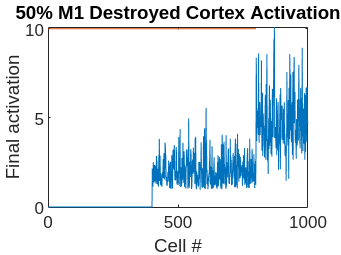

plot(x_0)
hold on
plot(10 * ones(1, m1_count))
hold off
title("50% M1 Destroyed Cortex Activation")
%ylim([0, 15])
ylabel("Final activation")
xlabel("Cell #")

saveas(gcf, 'images/M1Destroyed50Activations.png')

Net Activations compared to Forces

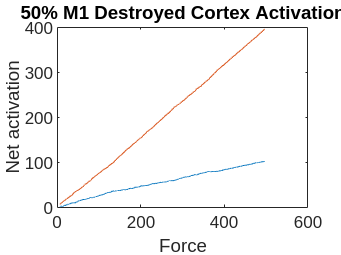

plot(final_forces, sma, final_forces, m1)

title("50% M1 Destroyed Cortex Activation")
ylabel("Net activation")
xlabel("Force")

saveas(gcf, 'images/M1Destroyed50NetActivations.png')